%% Problem 1 - Arnoldi Iteration Implementation
function [H, Q] = arnoldi_iteration(b, L, k, tol)
    % Implements the Arnoldi Iteration following Algorithm 16.1
    %
    % Parameters:
    % b   - Initial starting vector (column vector)
    % L   - Function handle representing the linear operator
    % k   - Number of Arnoldi iterations to perform
    % tol - Tolerance for stopping criterion (default: 1e-8)
    %
    % Returns:
    % H   - Upper Hessenberg matrix
    % Q   - Orthonormal basis for the Krylov subspace

    if nargin < 4
        tol = 1e-8; % Default tolerance if not provided
    end
    
    dim = length(b);
    Q = zeros(dim, k + 1, 'like', b); % Store orthonormal vectors
    H = zeros(k + 1, k, 'like', b);   % Upper Hessenberg matrix
    
    % Normalize the initial vector
    Q(:, 1) = b / norm(b);
    
    for j = 1:k
        v = L(Q(:, j)); % Apply linear operator
        
        % Modified Gram-Schmidt Orthogonalization
        for i = 1:j
            H(i, j) = Q(:, i)' * v; % Inner product (complex safe)
            v = v - H(i, j) * Q(:, i);
        end
        
        H(j + 1, j) = norm(v); % Compute next Hessenberg element
        
        if abs(H(j + 1, j)) < tol % Stopping criterion
            H = H(1:j, 1:j);
            Q = Q(:, 1:j);
            return;
        end
        
        Q(:, j + 1) = v / H(j + 1, j); % Normalize new vector
    end
    
    % Return computed Hessenberg matrix and orthonormal basis
    H = H(1:k, 1:k);
    Q = Q(:, 1:k);
end

%% Test Arnoldi Iteration on a Sample Matrix
function test_arnoldi()
    dim = 10; % Small test matrix
    A = rand(dim) + 1i * rand(dim); % Random complex matrix
    L = @(v) A * v; % Define linear operator
    b = rand(dim, 1) + 1i * rand(dim, 1); % Random initial vector
    k = 5; % Number of Arnoldi steps
    
    [H, Q] = arnoldi_iteration(b, L, k);
    
    % Check if H = Q' * A * Q
    A_approx = Q' * A * Q;
    error_norm = norm(A_approx - H);
    fprintf('Test Arnoldi Iteration: Error norm = %.5e\n', error_norm);
end
test_arnoldi()

Test Arnoldi Iteration: Error norm = 4.77607e-15


%% Problem 2 - Compute the Largest Ritz Values Using Arnoldi Iteration
function ritz_values = compute_ritz_values(L, dim, k, n)
 
    b = rand(dim, 1) + 1i * rand(dim, 1);
    
    % Perform Arnoldi Iteration
    [H, ~] = arnoldi_iteration(b, L, k);
    
    % Compute eigenvalues of the Hessenberg matrix H
    ritz_values = eig(H);
    
    % Sort eigenvalues by magnitude in descending order
    [~, idx] = sort(abs(ritz_values), 'descend');
    ritz_values = ritz_values(idx);
    
    % Return the n largest Ritz values
    ritz_values = ritz_values(1:n);
end

%% Problem 3 - Compute the Largest Eigenvalues of the FFT using Arnoldi Iteration
function fft_ritz_values = compute_fft_ritz_values(k, n)
    % Computes the n largest Ritz values of the FFT operator using Arnoldi iteration.
    %
    % Parameters:
    % k - Number of Arnoldi iterations to perform.
    % n - Number of Ritz values to return.
    %
    % Returns:
    % fft_ritz_values - Array of the n largest Ritz values.
    
    dim = 2^20; % Dimension of the space
    L = @(v) fft(v); % Define FFT as a linear operator
    
    % Compute the largest Ritz values using Arnoldi Iteration
    fft_ritz_values = compute_ritz_values(L, dim, k, n);
    
    % Display the computed Ritz values
    fprintf('Computed Ritz values for FFT:\n');
    disp(fft_ritz_values);
end
compute_fft_ritz_values(10, 4)

Computed Ritz values for FFT:
   1.0e+03 *

  -0.0000 - 1.0240i
   0.0000 + 1.0240i
  -1.0240 - 0.0000i
   1.0240 - 0.0000i



ans = 1.0e+03 *

  -0.0000 - 1.0240i
   0.0000 + 1.0240i
  -1.0240 - 0.0000i
   1.0240 - 0.0000i


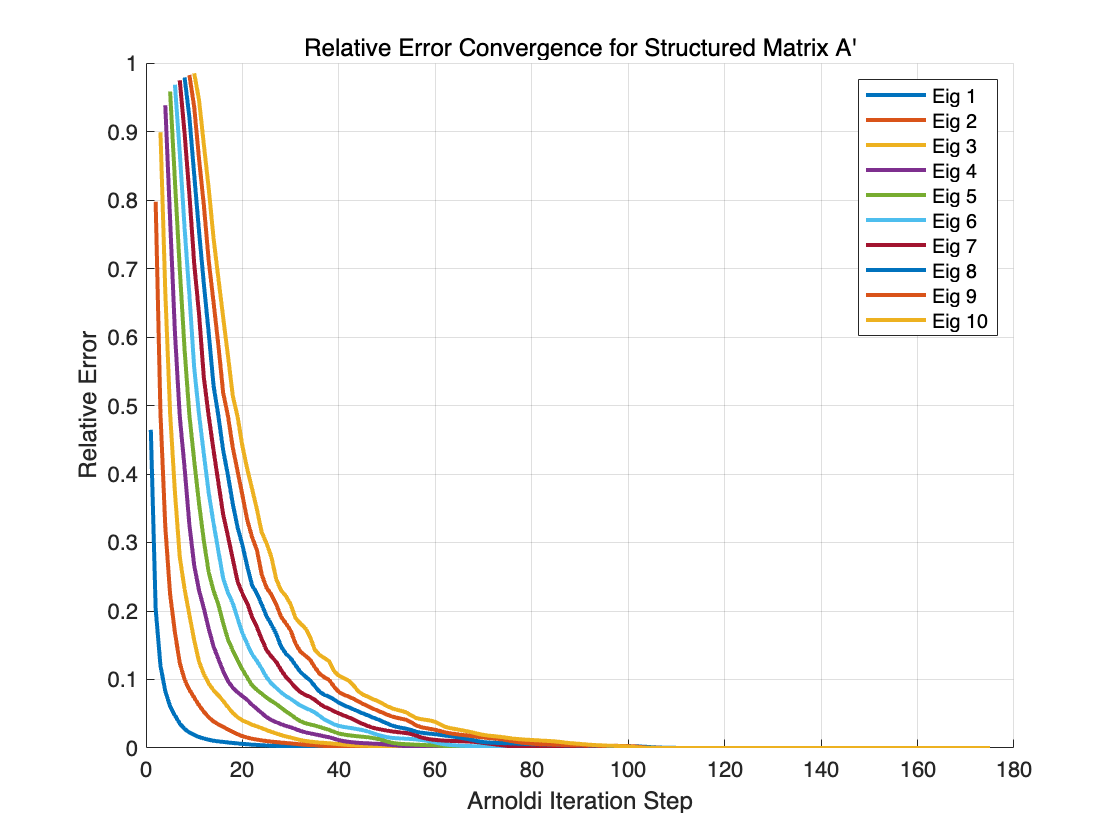



%% Problem 4 - Plot Relative Error Between Ritz Values and Eigenvalues
function plot_ritz_relative_error(A, n, iters)
    % Plots the relative error between the largest Ritz values and the largest eigenvalues of A.
    %
    % Parameters:
    % A     - Square matrix representing the linear operator.
    % n     - Number of largest eigenvalues to compare.
    % iters - Number of Arnoldi iterations to perform.
    %
    % The function computes the n largest eigenvalues of A, then iteratively computes
    % the Ritz values from Arnoldi iteration and plots the relative errors.

    dim = size(A, 1);
    L = @(v) A * v; % Define the linear operator
    
    % Compute the true n largest eigenvalues of A
    true_eigvals = eig(A);
    [~, idx] = sort(abs(true_eigvals), 'descend');
    true_eigvals = true_eigvals(idx(1:n));
    
    % Initialize error storage
    errors = NaN(iters, n);
    
    % Random starting vector
    b = rand(dim, 1) + 1i * rand(dim, 1);
    
    for k = 1:iters
        % Perform Arnoldi Iteration
        [H, ~] = arnoldi_iteration(b, L, k);
        
        % Compute the Ritz values
        ritz_vals = eig(H);
        [~, ritz_idx] = sort(abs(ritz_vals), 'descend');
        ritz_vals = ritz_vals(ritz_idx);
        
        % Compute relative errors for available Ritz values
        num_ritz = min(n, length(ritz_vals));
        errors(k, 1:num_ritz) = abs(true_eigvals(1:num_ritz) - ritz_vals(1:num_ritz)) ./ abs(true_eigvals(1:num_ritz));
    end
    
    % Plot errors
    figure;
    hold on;
    for i = 1:n
        plot(1:iters, errors(:, i), 'LineWidth', 2);
    end
    hold off;
    xlabel('Arnoldi Iteration Step');
    ylabel('Relative Error');
    title('Convergence of Ritz Values to True Eigenvalues (Relative Error)');
    legend(arrayfun(@(x) sprintf('Eig %d', x), 1:n, 'UniformOutput', false));
    grid on;
end

% Create a diagonal matrix with a structured spread of eigenvalues
D = diag(linspace(1, 300, 300)); % Evenly spaced eigenvalues

% Generate a random orthogonal matrix Q (QR decomposition ensures orthogonality)
[Q, ~] = qr(randn(300, 300)); 

% Construct a new well-conditioned matrix A'
A_prime = Q * D * Q';

% Run the relative error test
plot_ritz_relative_error(A_prime, 10, 175);
title('Relative Error Convergence for Structured Matrix A''');